# Read My Writing

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

## Setting Up MATLAB Mobile

1) [Install MATLAB Mobile](https://www.mathworks.com/help/matlabmobile/ug/install-matlab-mobile-on-your-device.html) on a cell phone or tablet through the relevant app store.

2) Open MATLAB Mobile and select the hamburger icon in the top left of the window:

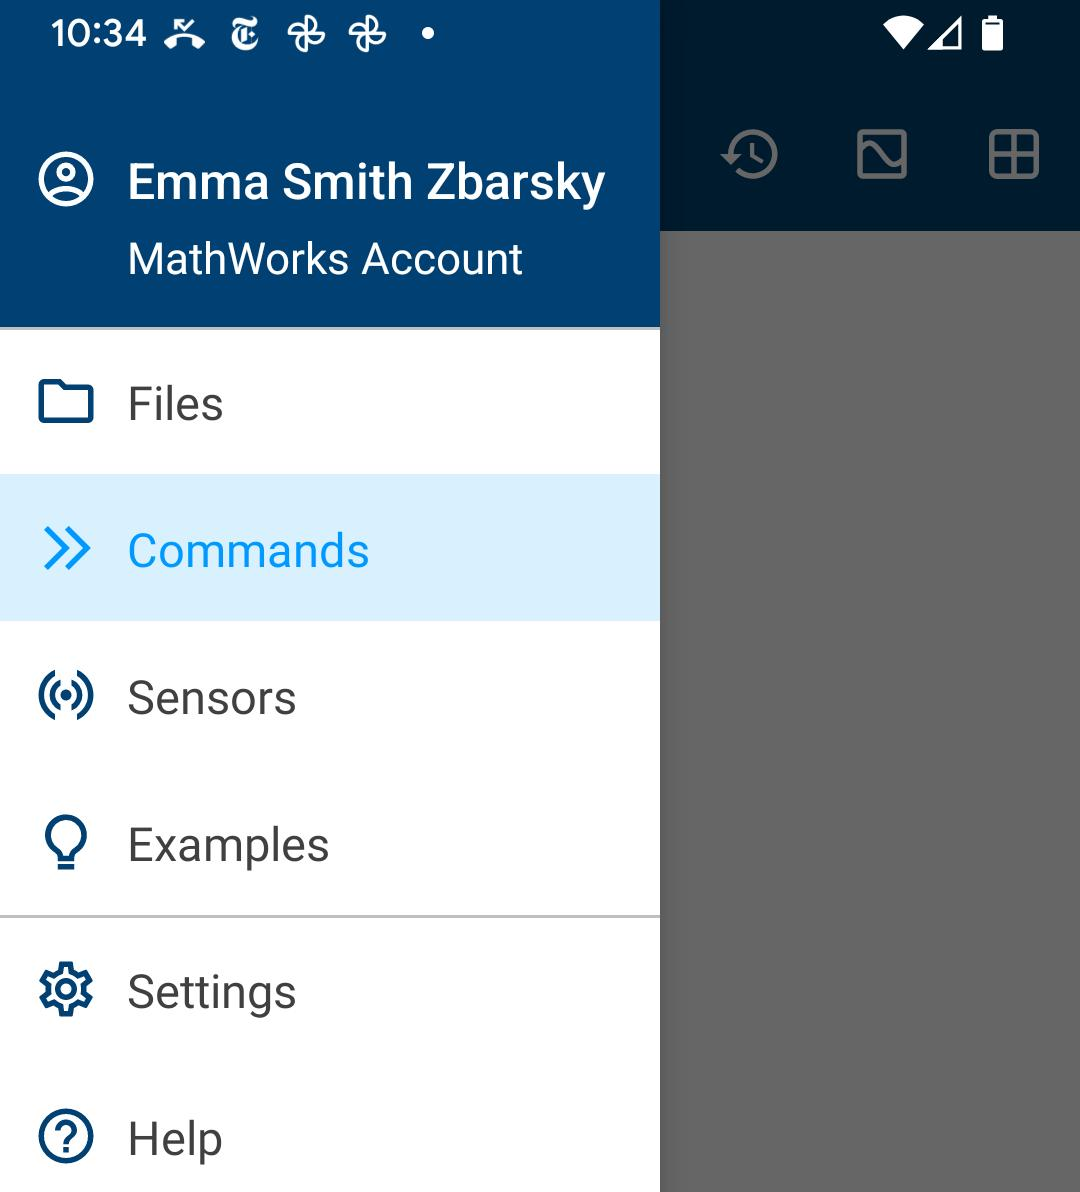

3) Select "Sensors" and then select "More"

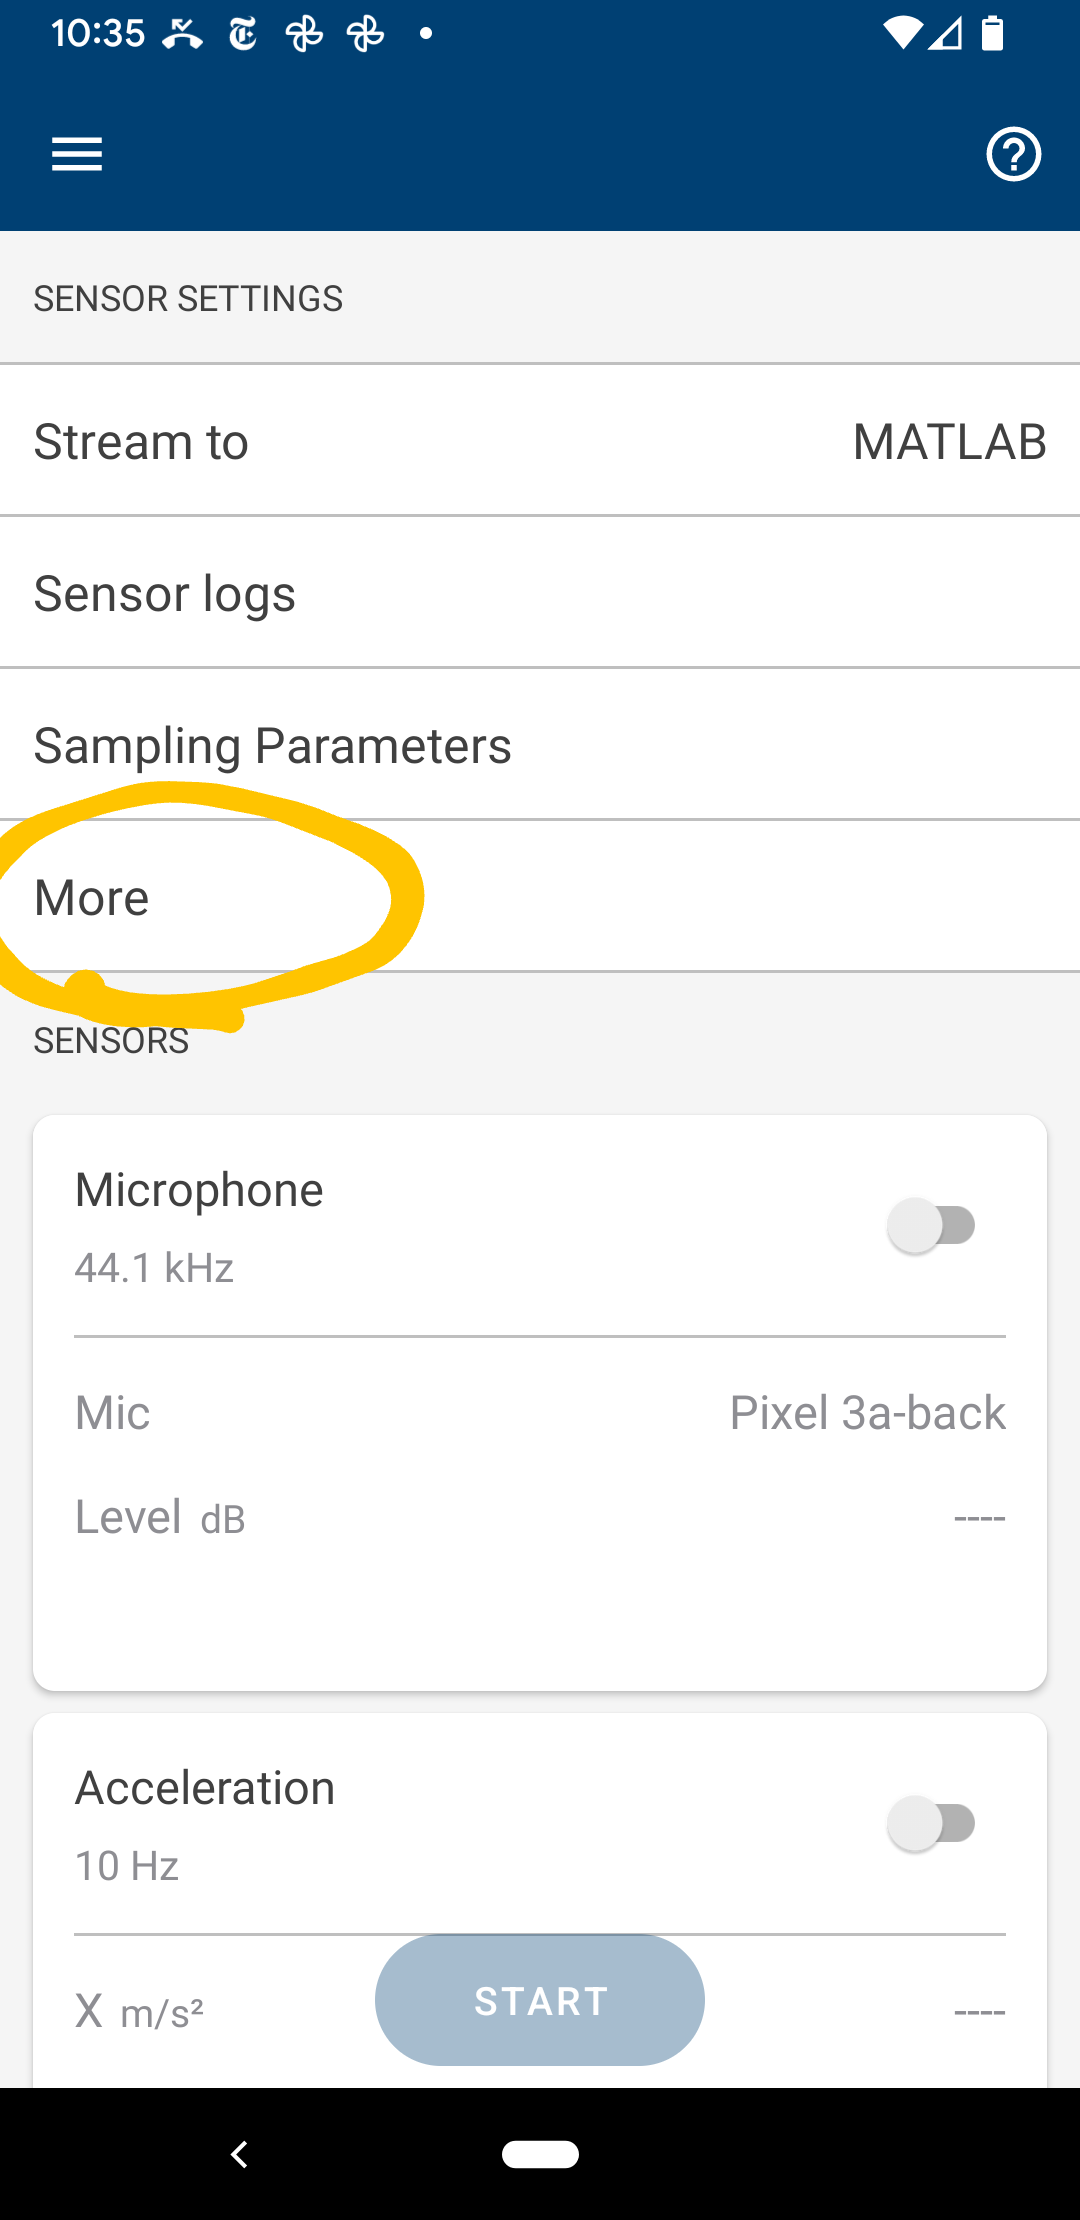

4) Turn on "Sensor Access" and "Camera Access". The name of the device you are using will be visible on this screen as well:

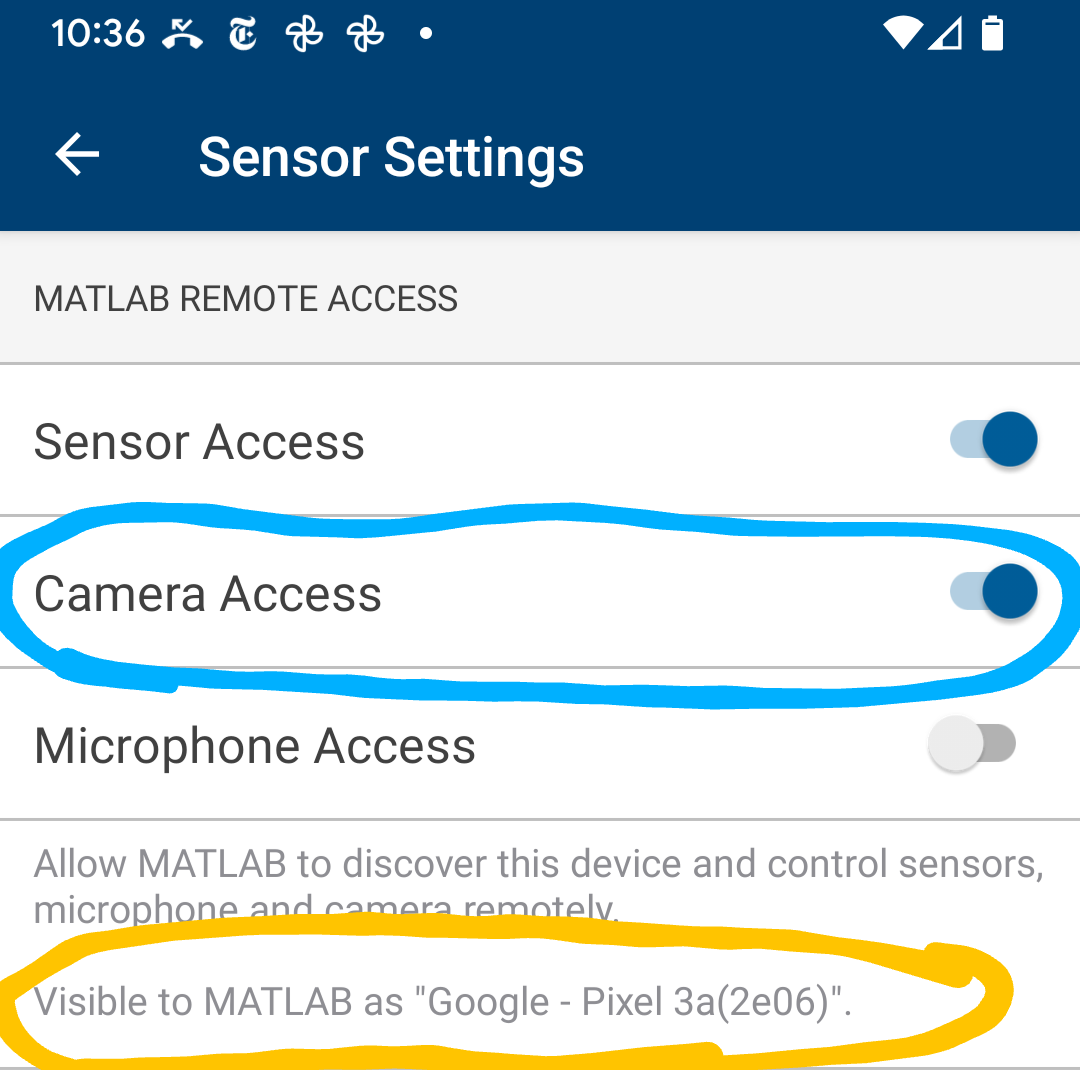

5) Make sure that you are signed in to your MathWorks account. This should be automatic in MATLAB Online and is visible on the top right on Desktop.

6) You need the MATLAB Android Sensors or MATLAB iOS Sensors support package before you can use this feature. Open [Add-On Explorer](matlab: matlab.addons.supportpackage.internal.explorer.showSupportPackages({'ML_ANDROID_SENSORS', 'ML_APPLE_IOS_SENSORS'}, 'tripwire');) to install the required support package.

## Write a Digit

Write an Arabic numeral, 0-9. 

## Take a Photograph of your Digit

Run this code to connect this MATLAB instance to the MATLAB Mobile instance. Then use the camera feature on your phone or tablet to take a photo of the digit you have written down. This will save your image as a `png` in a folder called "Photographs" as `myImgN.png`.

 
if ~exist("m","var")
    m = mobiledev(mobiledevlist().Device{1});
end
if ~exist("c","var")
    c = camera(m);
    c.Autofocus = 'on';
    myCameraResolutions = string.empty(0,1+length(c.AvailableResolutions));
    myCameraResolutions(1) = string(c.Resolution);
    for r = 1:length(c.AvailableResolutions)
        myCameraResolutions(r) = string(c.AvailableResolutions{r});
    end
    c.Resolution = myCameraResolutions(2);
end
img = snapshot(c,"manual");
files = dir(fullfile("Data" + filesep + "Photographs", '*.png'));
numPNG = length(files);
try
    imwrite(img,fullfile("Data","Photographs","myImg" + numPNG + ".png"),"png")
catch ME
    warning("Failed to save your file for future reference.")
end

## Preparing an Image

First, we need to look at the image we have recorded:

If the digit is not oriented upright in `img`, rotate the image until it is using `rot90.` Check the box below and then click the Display Image button until the digit is oriented upright.

if false
    img = rot90(img); %#ok<UNRCH>
end
imshow(img)

### Identify the Digit of Interest

First use `imtool` to crop out a single digit and minimize background. Double-click on the area you selected to crop the image. Then export the result to the workspace as `imgCropped`. 

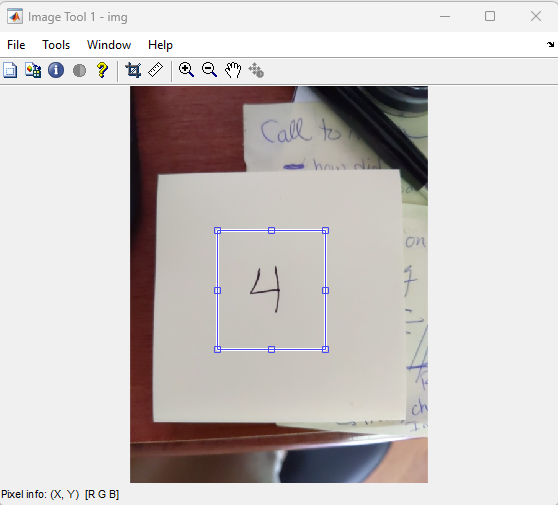

imtool(img)    

Then export the result to the workspace as `imgCropped`.

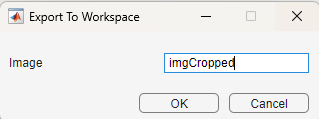

### Create a Black and White Mask of Your Digit

Mask your image to isolate the digit in white with a black background. 

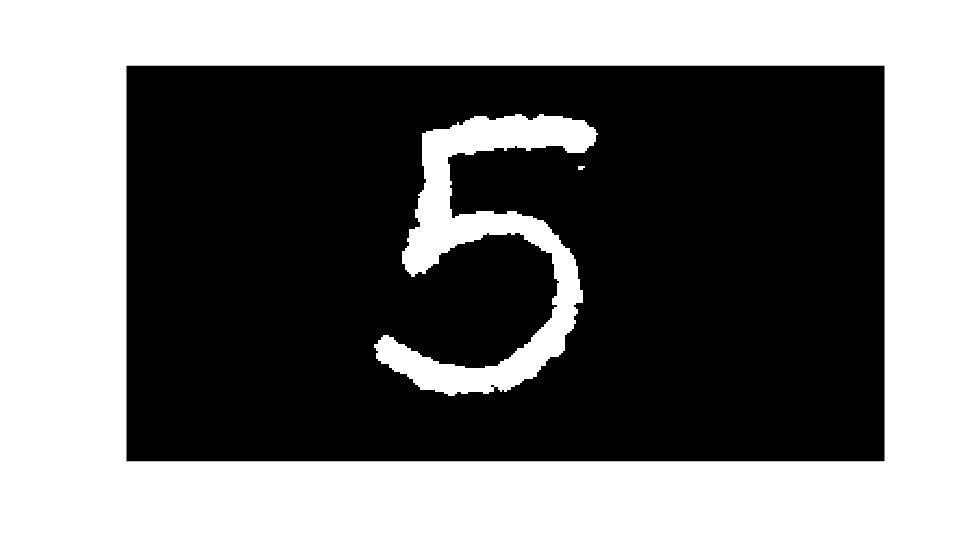

 
% Threshold image with global threshold
BW = imbinarize(im2gray(imgCropped));

% Invert mask
imgBW = imcomplement(BW);

imshow(imgBW,"InitialMagnification","fit")

If this fails to clearly identify the digit, you can use the `imageSegmenter` app interactively to create a black and white masked version of your digit where the background is black and the digit is white. Export the final segmentation as `imgBW.`

if false
imageSegmenter(imgCropped) %#ok<UNRCH>
end

### Center and Zoom In on Your Digit

To use a simple vector space method of digit identification, we need to standardize the zoom, image location, and overall pixel size of our images. 

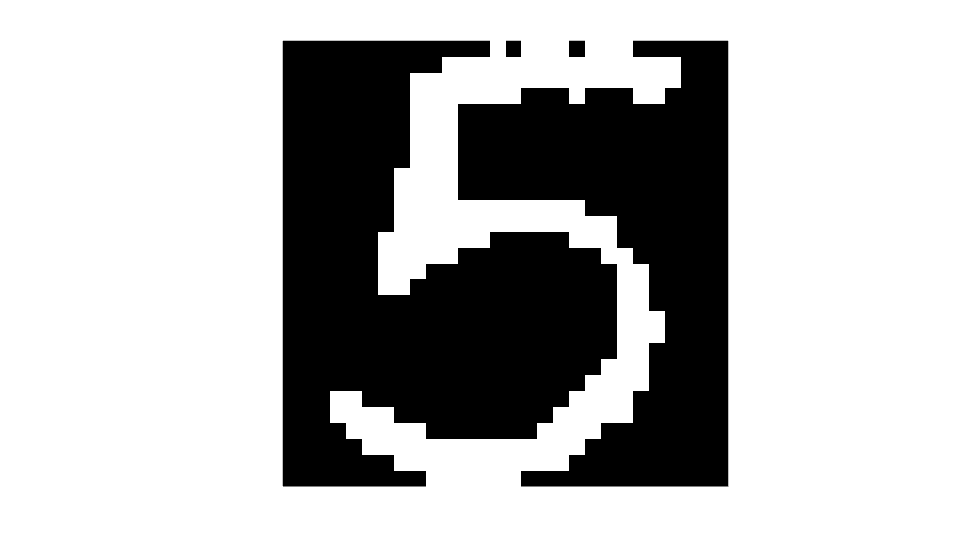

% Ensure that the image registers a connected image
myComponents = bwconncomp(imgBW).NumObjects;
if myComponents > 3
    se = strel("disk",2);
    imgBW = imopen(imgBW,se);
    imshow(imgBW)
end

imSize = 28;
curDigit = ZoomIn(imgBW,imSize);

% Ensure that the pen stroke used is sufficiently robust to 
% register in the downsized version
myComponents = bwconncomp(curDigit).NumObjects;
myDensity = nnz(curDigit(:))/length(curDigit(:));
cnt = 0;
while (myComponents > 1 || myDensity < 0.18) && cnt < 10 
    cnt = cnt + 1;
    se = strel("disk",2+cnt);
    imgBW2 = imdilate(imgBW,se);
    curDigit = ZoomIn(imgBW2,imSize);
    myDensity = nnz(curDigit(:))/length(curDigit(:));
    myComponents = bwconncomp(curDigit).NumObjects;
end
imshow(curDigit,"InitialMagnification","fit")

## Save Digit to Array

When you are satisfied with your processed digit image, save it for analysis.

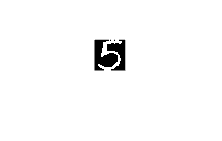

 
if ~exist("myDigits","var")
    myDigits = curDigit(:);
else
    myDigits = [myDigits curDigit(:)];
end
imshow(reshape(myDigits,imSize,[]))

Repeat, as desired to add more digits.

## Identifying a Digit

 
load("trainedData.mat","U","r")
[~,numTest] = size(myDigits);

myResults = zeros(1,numTest);
allDist = zeros([numTest 10]);
for testIdx = 1:numTest
    myDigitCol = double(Im2Vec(myDigits(:,testIdx)));
    for k = 1:10
        allDist(testIdx,k) = calcDistance(myDigitCol,U(:,:,k),r(k));
    end
    [~,idx] = min(allDist(testIdx,:));
    myResults(testIdx)=idx-1;
end
imshow(reshape(myDigits,imSize,[]))

myResults;
disp("In order, these are identified as:")

In order, these are identified as:


disp(myResults)

     5



myIndices = string((1:length(myResults))');

## Exploring Results

myIdx = double(myIndices(1));

You have selected: 

imshow(reshape(myDigits(:,myIdx),imSize,[]))

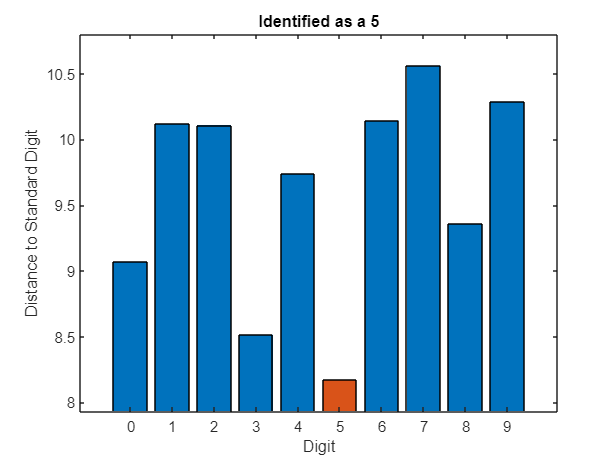

figure
bar(0:9,allDist(myIdx,:),"SeriesIndex",1);
title("Identified as a " + myResults(myIdx))
hold on
myRange = range(allDist(myIdx,:));
minVal = allDist(myIdx,myResults(myIdx)+1);
bar(myResults(myIdx),minVal,"SeriesIndex",2);
ylim([minVal-0.1*myRange minVal+1.1*myRange])
xlabel("Digit")
ylabel("Distance to Standard Digit")
hold off

function dist = calcDistance(q,U,r)

if class(q) == "single" || class(q) == "uint8"
    q = double(q);
end

%qU = q'*U;

%myTot = q;

proj = 0;
for k = 1:r
    proj = proj+dot(q,U(:,k))*U(:,k);
    %    qUk = q'*U(:,k);
%    myTot = myTot - qUk*U(:,k);
end

myTot = q-proj;

% dist = sqrt(myTot'*myTot);
dist = norm(myTot);
end

function vec = Im2Vec(im)
vec = im(:);
end